## Systemparameter

D = 1;
DD = D;
b = 0;
J = 10;

Die *langsame* Frequenz ergibt sich durch $\sqrt{\frac{D}{J}} = \omega_a$, die *schnelle* Frequenz durch $\sqrt{\frac{D+DD}{J}} = \omega_b$ bzw. $\sqrt{\frac{2D}{J}}$ für den Fall gleicher Federkonstanten.

## Anfangsbedingungen

maxphi = pi;
minphi = -pi;
phi10 = -0.11;
phi20 = -0.71;

### Plot Settings

n = 3;
T = 2*pi/sqrt(D/J);
t = linspace(0,n*T,1000);
[p1 p2] = auslenkungen(t,phi10,phi20,D,DD,b,J);

clf;
plot(t,p1);
hold;

Current plot held


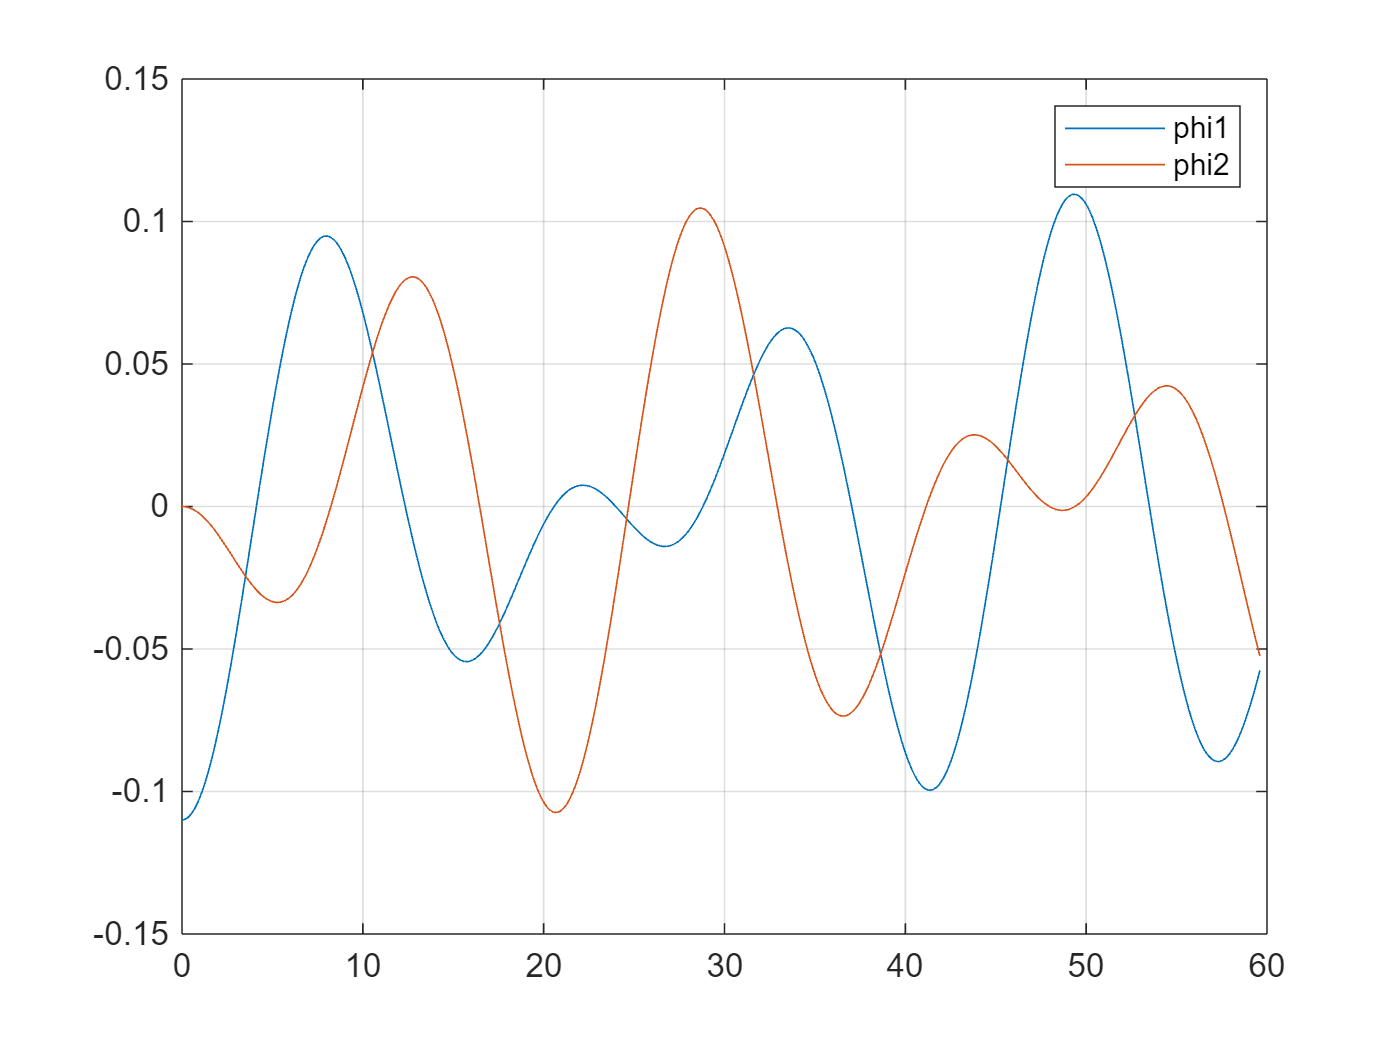

plot(t,p2);
legend('phi1','phi2')
grid
hold off;


$$\partial_t^2 (\phi_1+\phi_2)+ \frac{b}{J}\partial_t (\phi_1+\phi_2) + \frac{D}{J}(\phi_1+\phi_2) = \hat{M}_e \sin(\omega_e t)$$
